CARLOS ADRIAN DELGADO VAZQUEZ A01735818

REPORTE DE SEGUIMIENTO DE PASOS

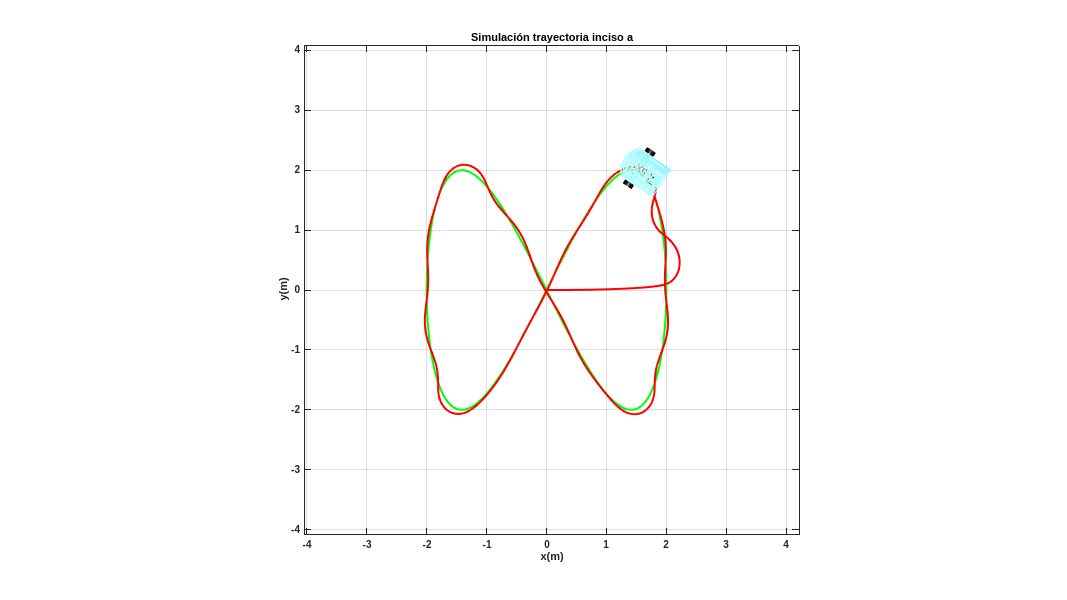

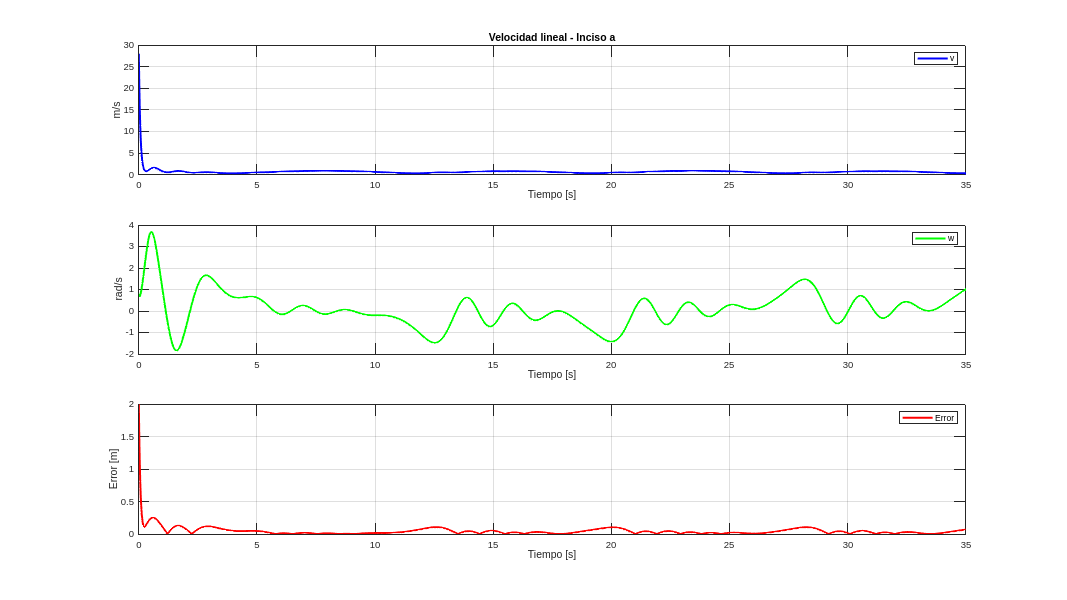

Simulación inciso a finalizada.


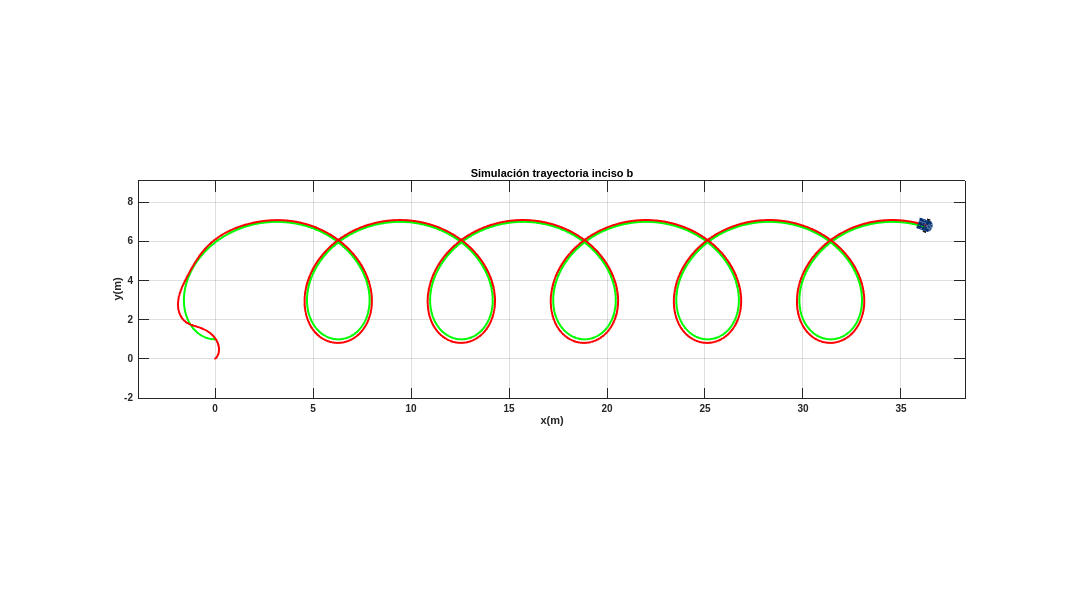

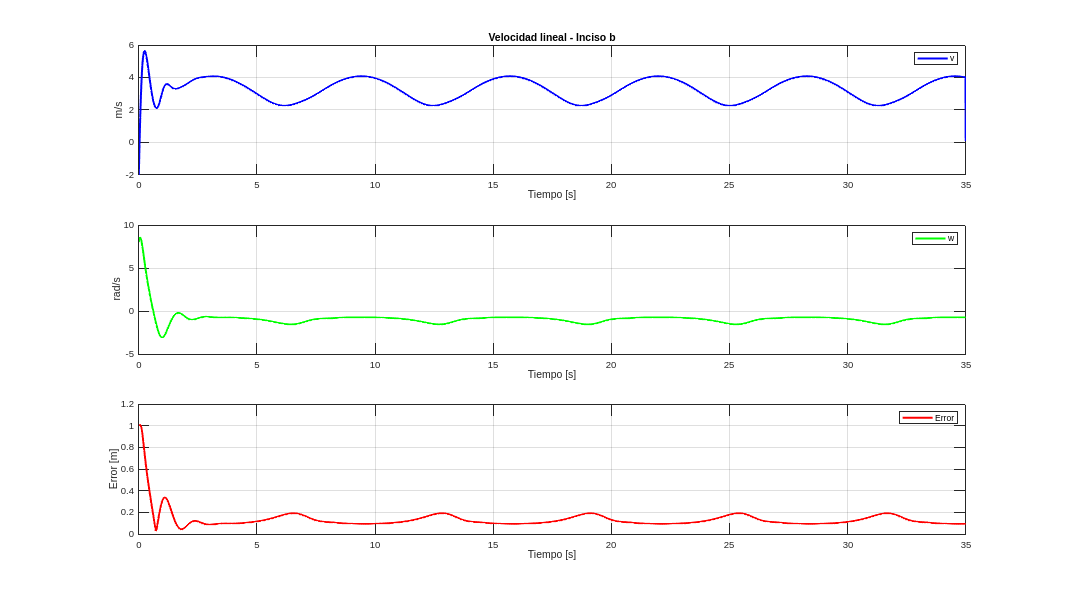

Simulación inciso b finalizada.


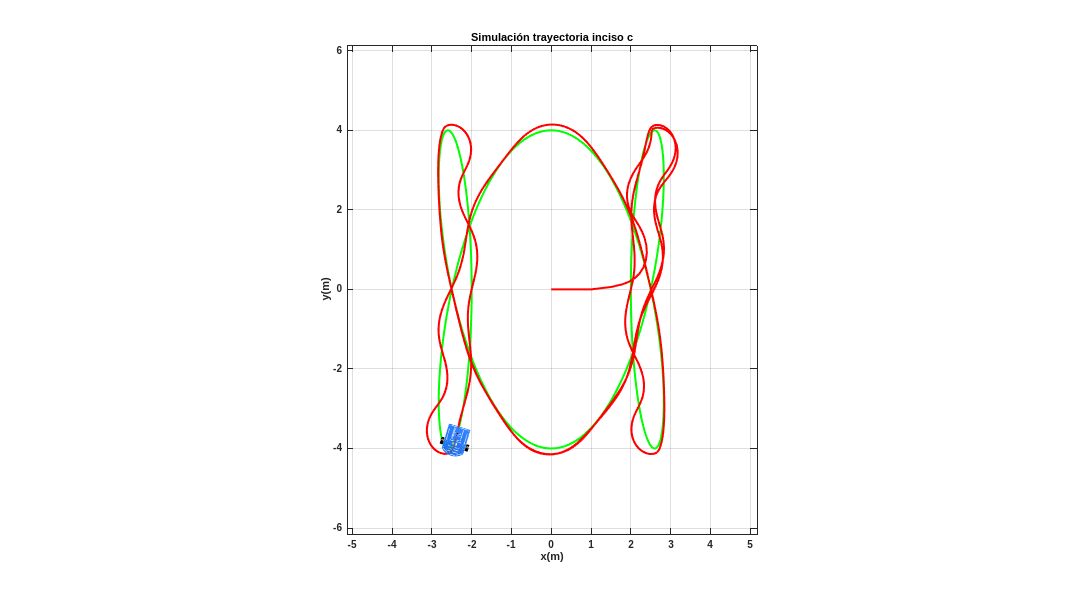

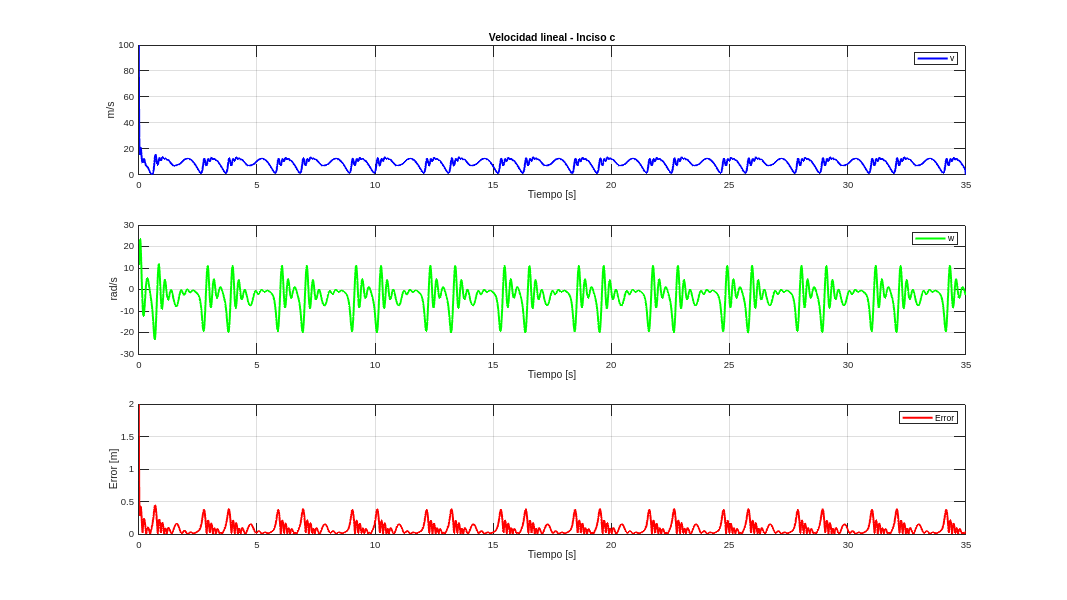

Simulación inciso c finalizada.


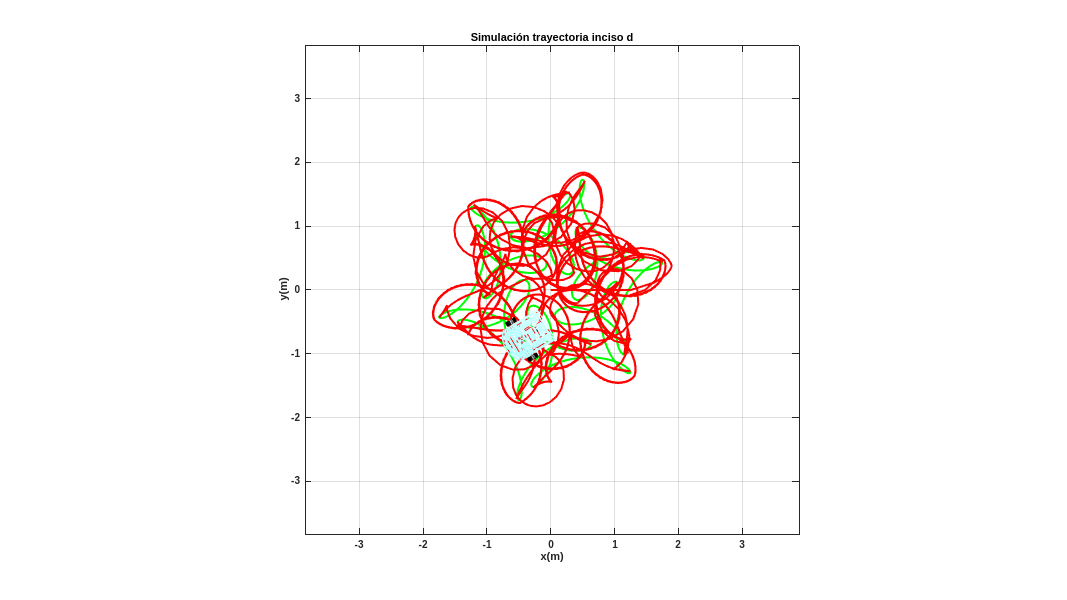

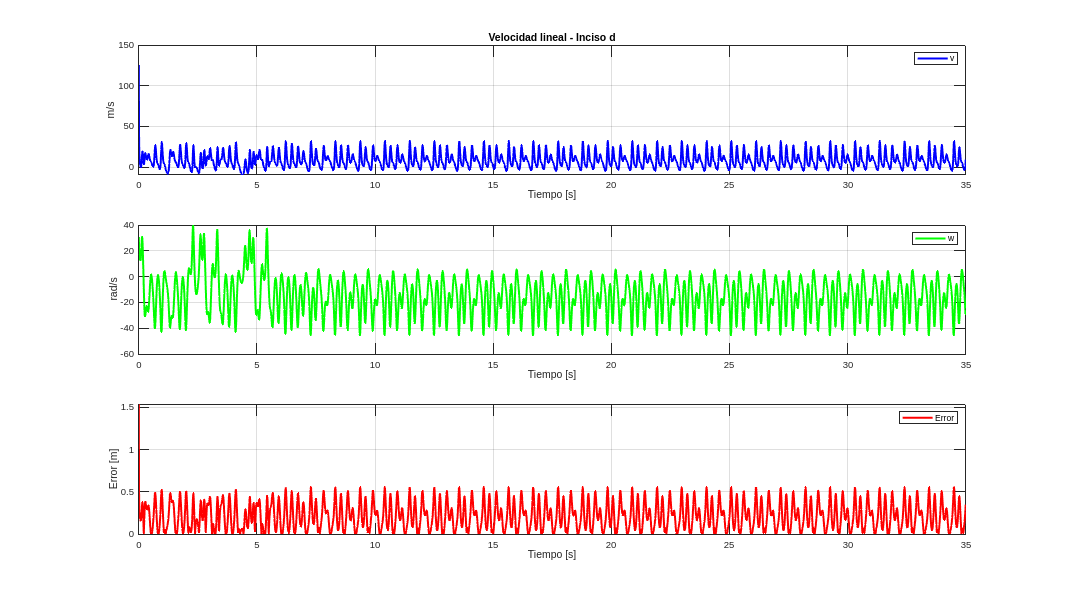

Simulación inciso d finalizada.


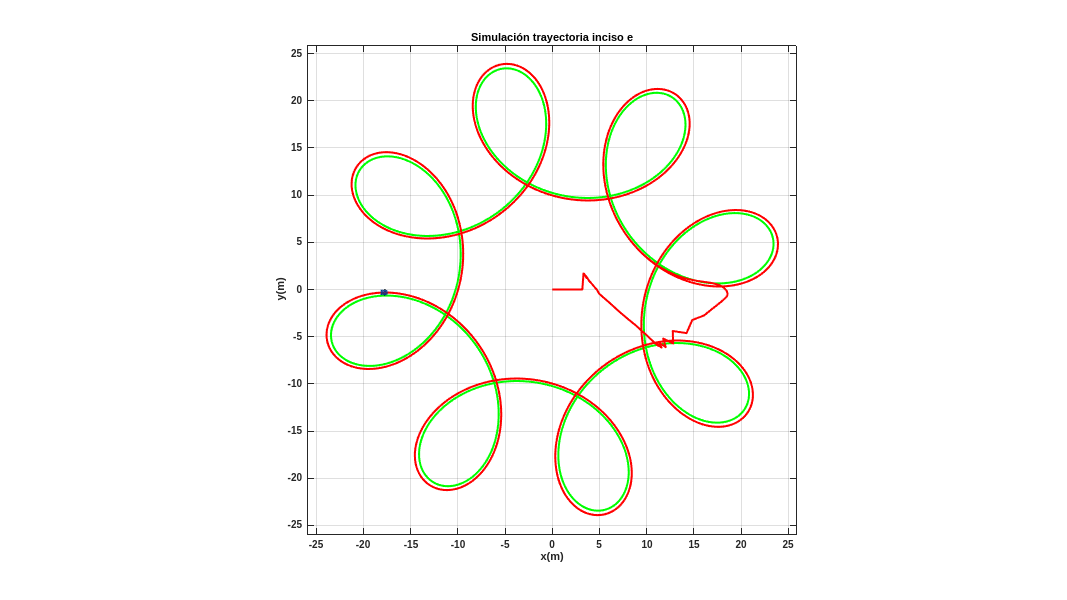

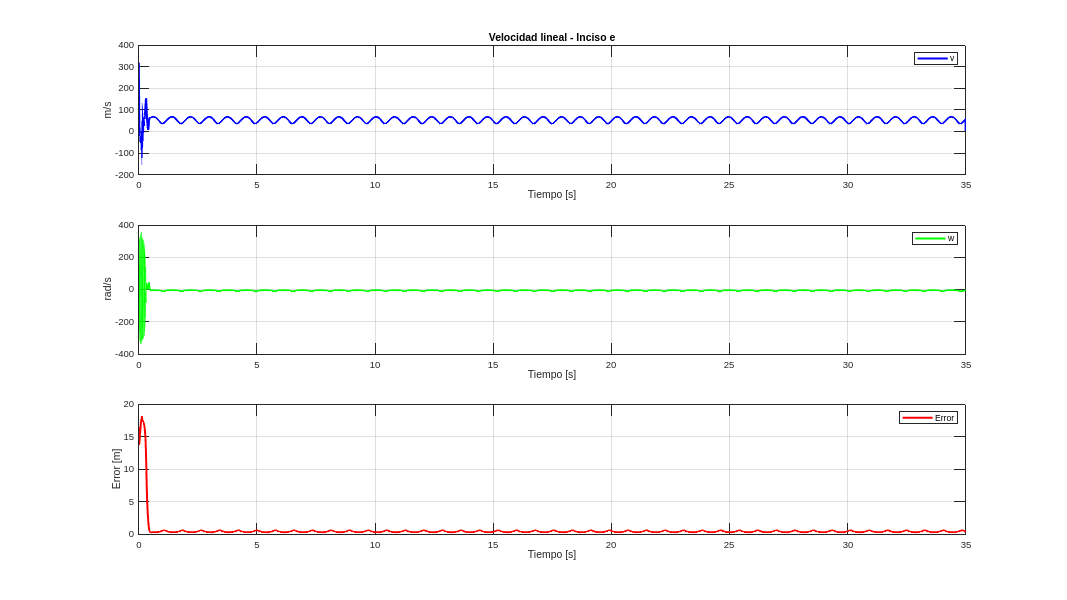

Simulación inciso e finalizada.


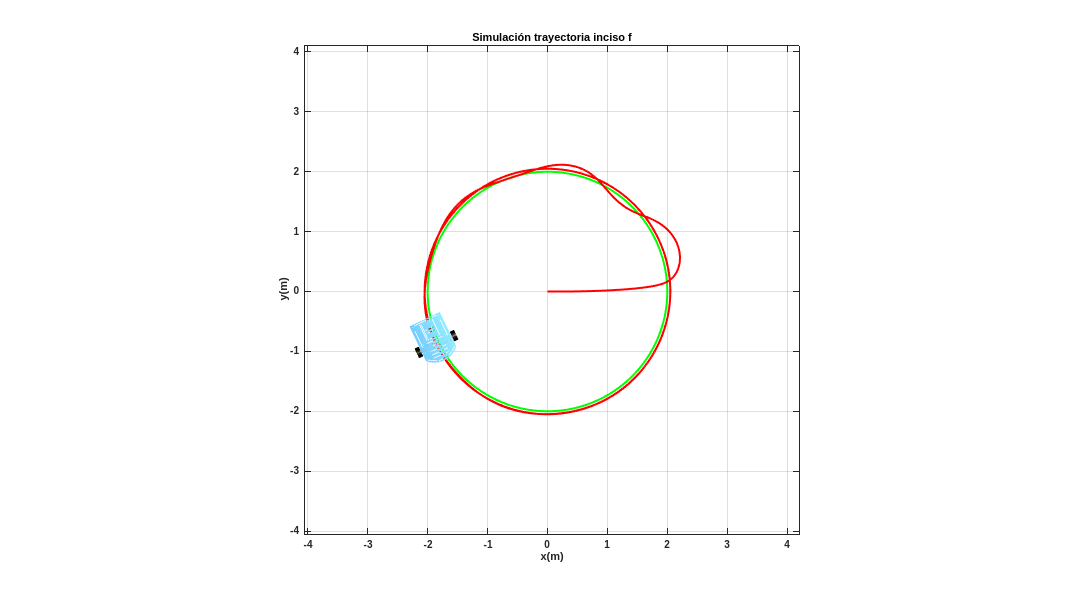

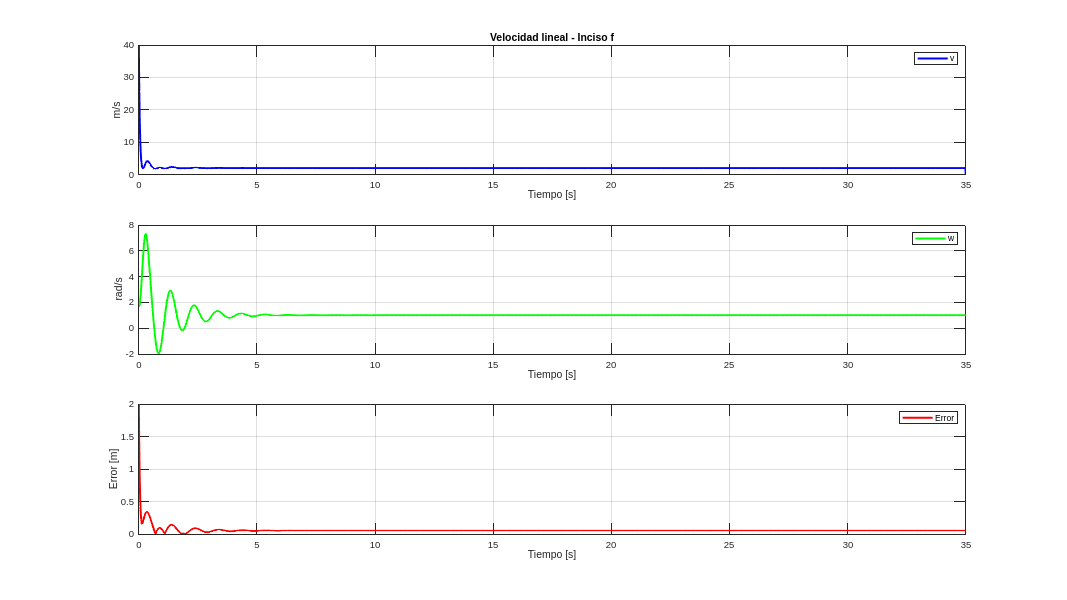

Simulación inciso f finalizada.


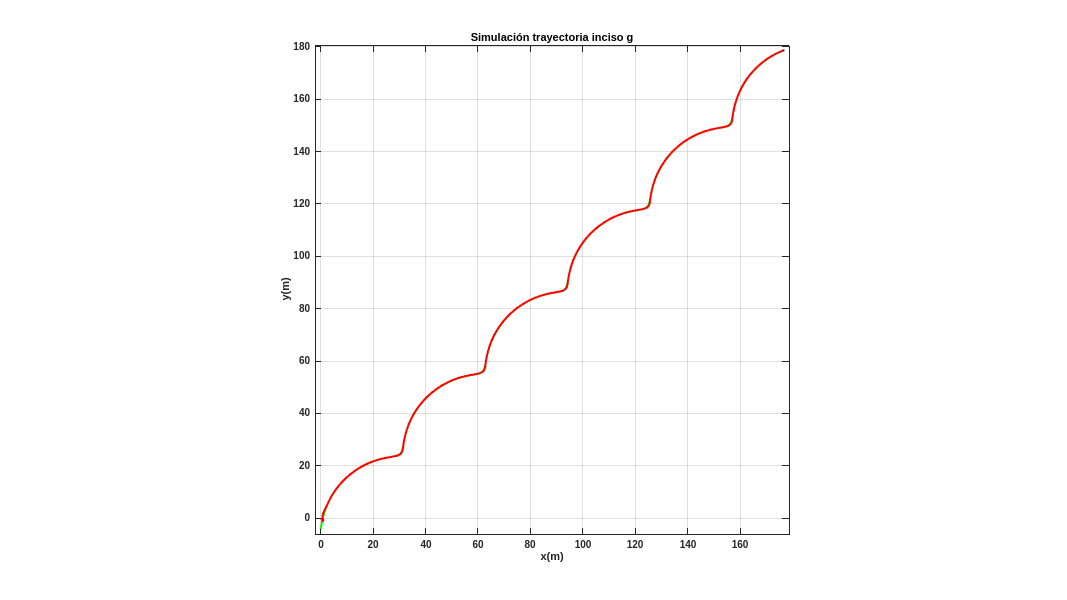

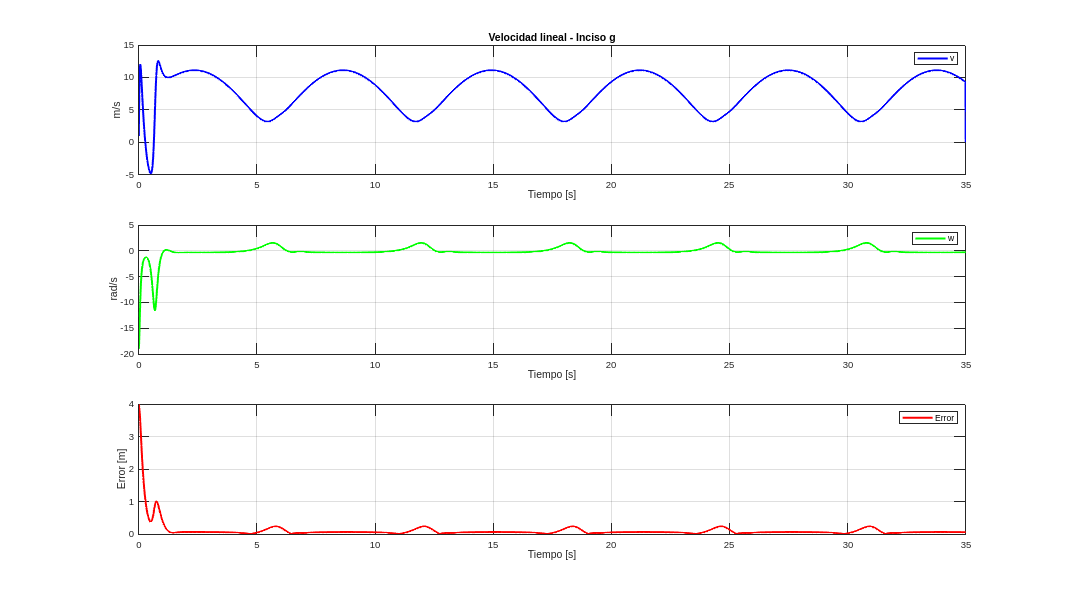

Simulación inciso g finalizada.


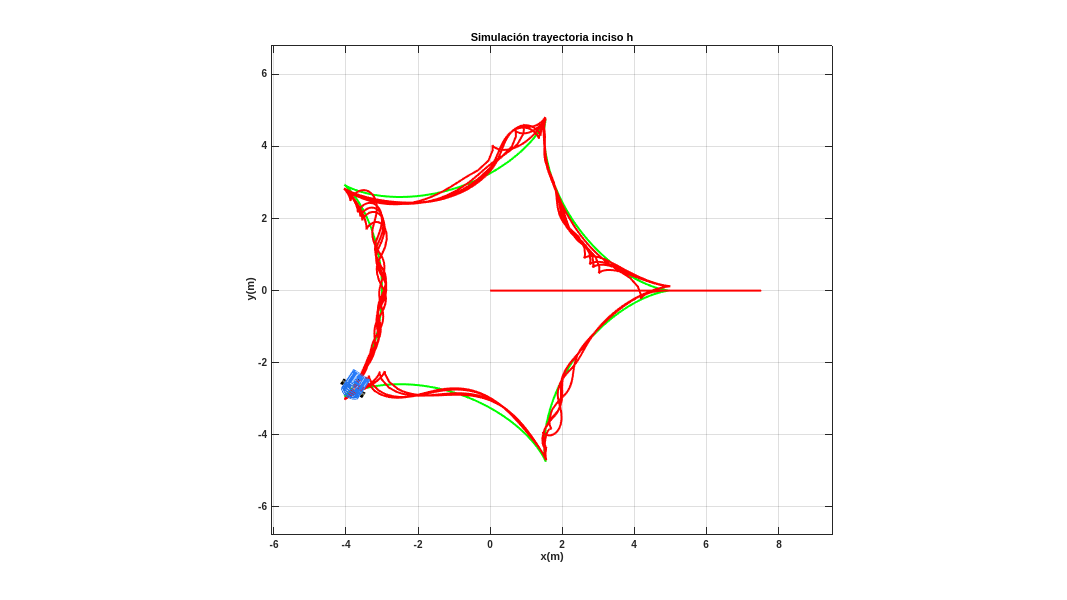

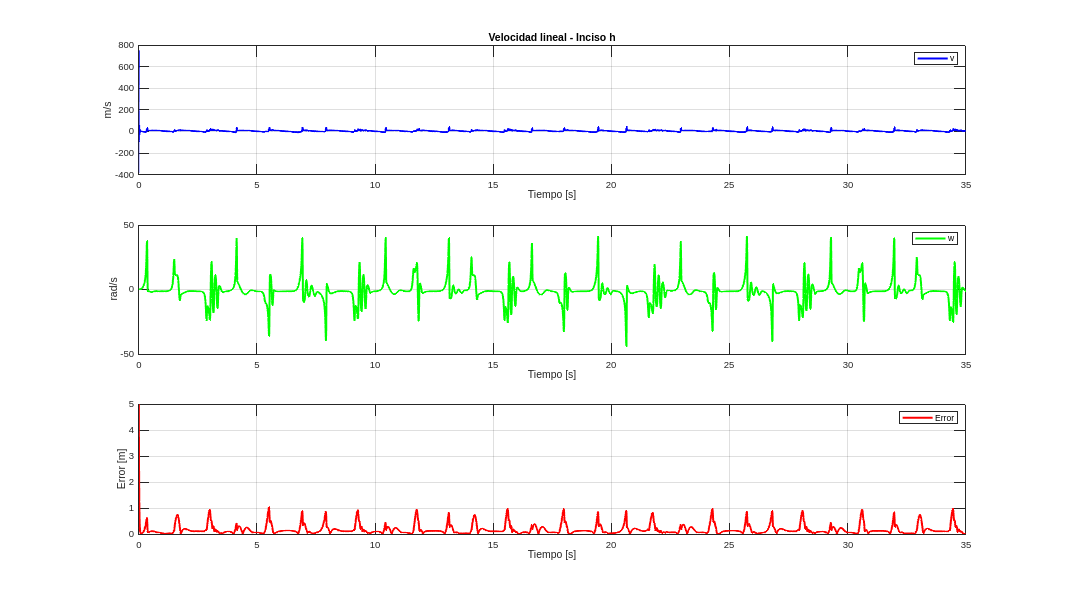

Simulación inciso h finalizada.


% Limpieza de pantalla
clear all
close all
clc

% 1. Tiempo de simulación
tf = 35;             % Tiempo de simulación en segundos
ts = 0.01;           % Tiempo de muestreo en segundos
t = 0:ts:tf;         % Vector de tiempo
N = length(t);       % Número de muestras

% 2. Definición de trayectorias (a-h)
trayectorias = {
   2*cos(0.2*t), 2*sin(0.4*t);                          % a)
   t-3*sin(t), 4-3*cos(t);                              % b)
   3*cos(t)-cos(3*t), 4*sin(3*t);                       % c)
    cos(t)+0.5*cos(7*t)+1/3*sin(17*t), sin(t)+0.5*sin(7*t)+1/3*cos(17*t); % d)
    17*cos(t)+7*cos(17+7*t), 17*sin(t)-7*sin(17+7*t);     % e)
   2*cos(t), 2*sin(t);                                  % f)
    5*t-4*sin(t), 5*t-4*cos(t);                          % g)
   4*cos(t)+cos(4*t), 4*sin(t)-sin(4*t);                % h)
};

% 3. Definición de ganancias K por cada trayectoria
% Puedes ajustar estos valores de ganancia más adelante si ves que alguna trayectoria se "descontrola" o no se sigue bien
ganancias_K = {
   [14 0; 0 14];  % a)
   [8 0; 0 8];    % b)
   [50 0; 0 50];  % c)
    [80 0; 0 80];  % d)
   [18 0; 0 18];  % e) 
   [20 0; 0 20];    % f)
    [6 0; 0 6];    % g) 
   [150 0; 0 12];  % h) 
};

% 4. Bucle para simular cada trayectoria
for caso = 1:8

    % Condiciones iniciales
    x1(1) = 0;
    y1(1) = 0;
    phi(1) = 0;

    hx(1) = x1(1);
    hy(1) = y1(1);

    % Trayectoria deseada
    hxd = trayectorias{caso,1};
    hyd = trayectorias{caso,2};

    % Derivadas aproximadas (velocidades deseadas)
    hxdp = [diff(hxd)/ts, 0];
    hydp = [diff(hyd)/ts, 0];

    % Prealocaciones
    Error = zeros(1,N);
    v = zeros(1,N);
    w = zeros(1,N);

    % Selección de la ganancia correspondiente
    K = ganancias_K{caso};

    % 5. Control, bucle de simulación
    for k = 1:N 
        hxe(k) = hxd(k) - hx(k);
        hye(k) = hyd(k) - hy(k);

        he = [hxe(k); hye(k)];
        Error(k) = sqrt(hxe(k)^2 + hye(k)^2);

        J = [cos(phi(k)) -sin(phi(k));
             sin(phi(k))  cos(phi(k))];

        hdp = [hxdp(k); hydp(k)];

        qpRef = pinv(J)*(hdp + K*he);

        v(k) = qpRef(1);
        w(k) = qpRef(2);

        % Aplicación de control
        phi(k+1) = phi(k) + w(k)*ts;

        xp1 = v(k)*cos(phi(k));
        yp1 = v(k)*sin(phi(k));

        x1(k+1) = x1(k) + ts*xp1;
        y1(k+1) = y1(k) + ts*yp1;

        hx(k+1) = x1(k+1);
        hy(k+1) = y1(k+1);
    end

    % 6. Simulación Virtual 3D

    figure;
    set(gcf,'Color','white');
    set(gca,'FontWeight','bold');
    sizeScreen = get(0,'ScreenSize');
    set(gcf,'position',sizeScreen);
    camlight('headlight');
    axis equal;
    grid on;
    box on;
    xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
    view([-0.1 90]);

    % ==== Nueva sección: ajustar límites automáticamente ====
    margen = 2; % margen adicional para que no quede pegado al borde
    x_min = min([hxd, hx]) - margen;
    x_max = max([hxd, hx]) + margen;
    y_min = min([hyd, hy]) - margen;
    y_max = max([hyd, hy]) + margen;
    axis([x_min x_max y_min y_max 0 1]); 
    % =======================================================

    title(['Simulación trayectoria inciso ', char('a'+caso-1)]);

    % b) Graficar robot en la posición inicial
    scale = 4;
    MobileRobot_5; % Asegúrate que esta función esté disponible
    H1=MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;

    % c) Graficar trayectorias
    H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
    H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); 

    step = 5; % pasos para la animación
    for k=1:step:N
        delete(H1);    
        delete(H2);

        H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
        H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);

        pause(ts);
    end


    % 7. Gráficas de velocidades y error
    figure;
    set(gcf,'position',sizeScreen);
    subplot(311)
    plot(t,v,'b','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('m/s'),legend('v');
    title(['Velocidad lineal - Inciso ', char('a'+caso-1)]);
    subplot(312)
    plot(t,w,'g','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('rad/s'),legend('w');
    subplot(313)
    plot(t,Error,'r','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('Error [m]'),legend('Error');

    % Pausa para pasar al siguiente inciso
    disp(['Simulación inciso ', char('a'+caso-1), ' finalizada.']);
end

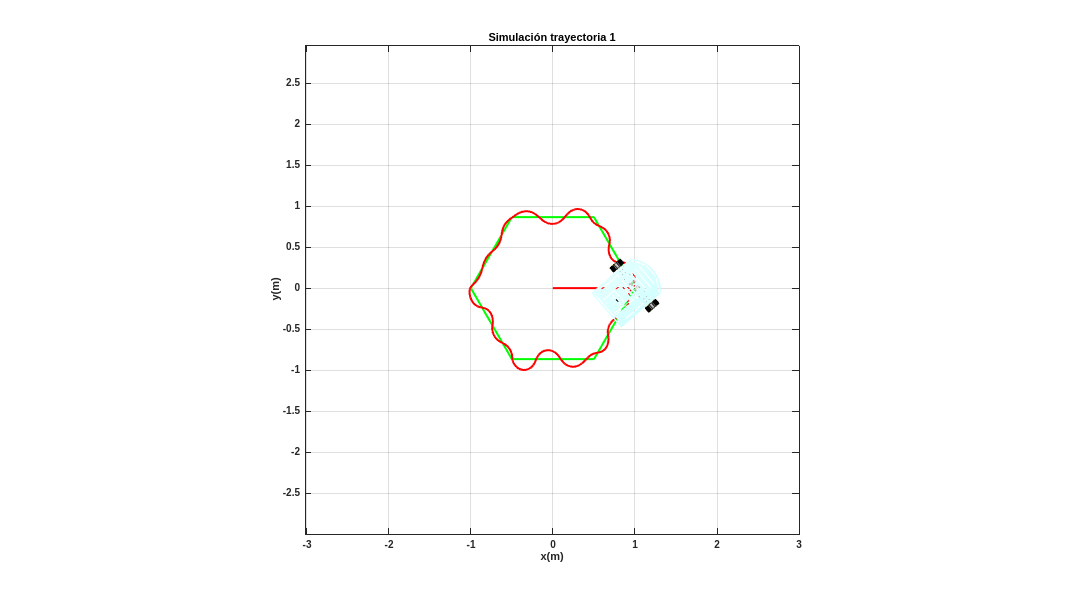

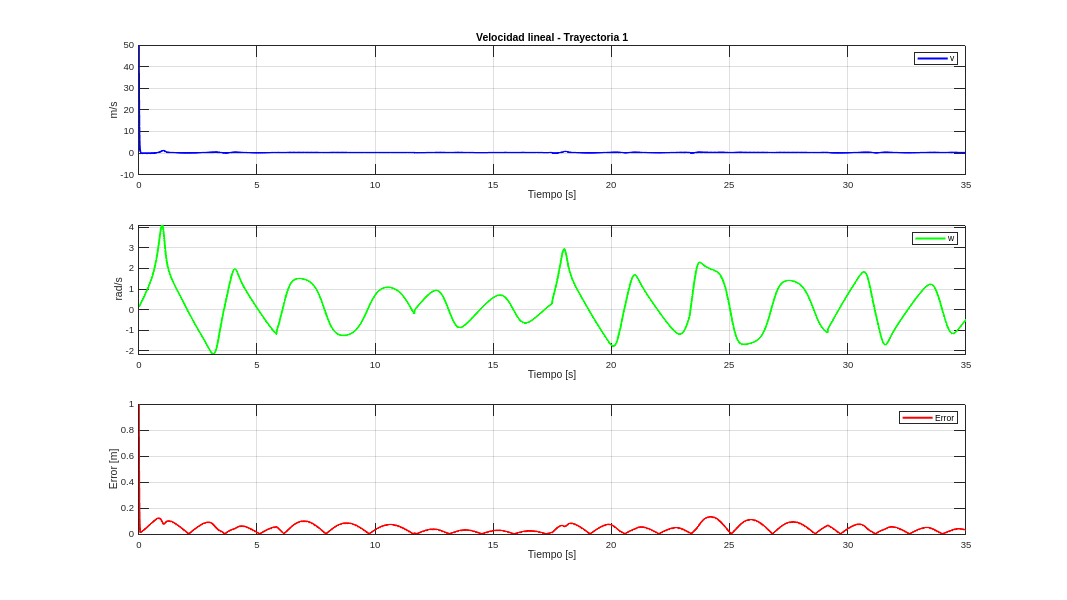

Simulación trayectoria 1 finalizada.


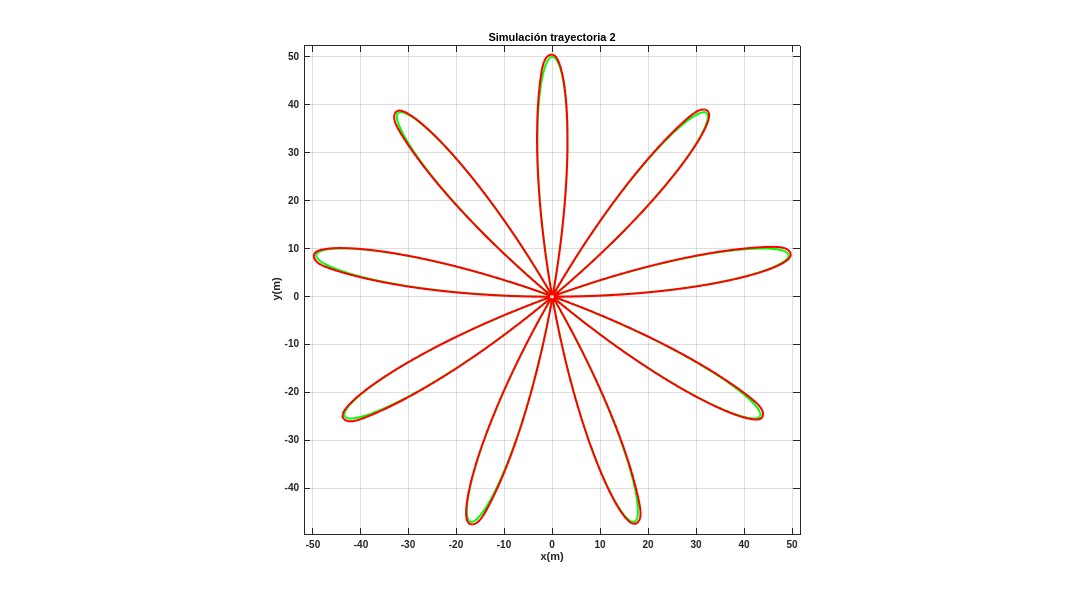

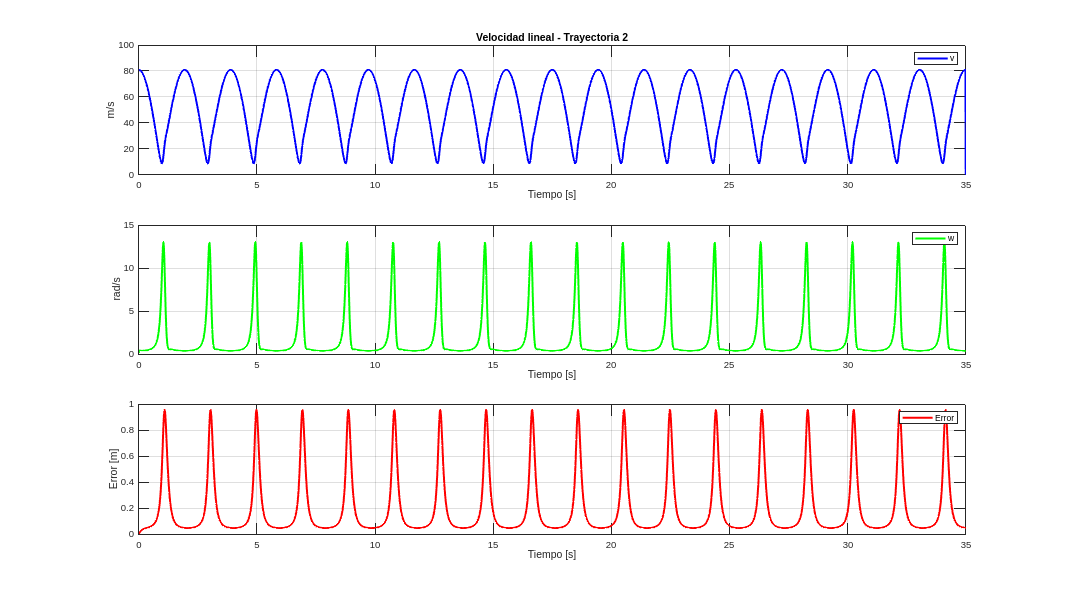

Simulación trayectoria 2 finalizada.


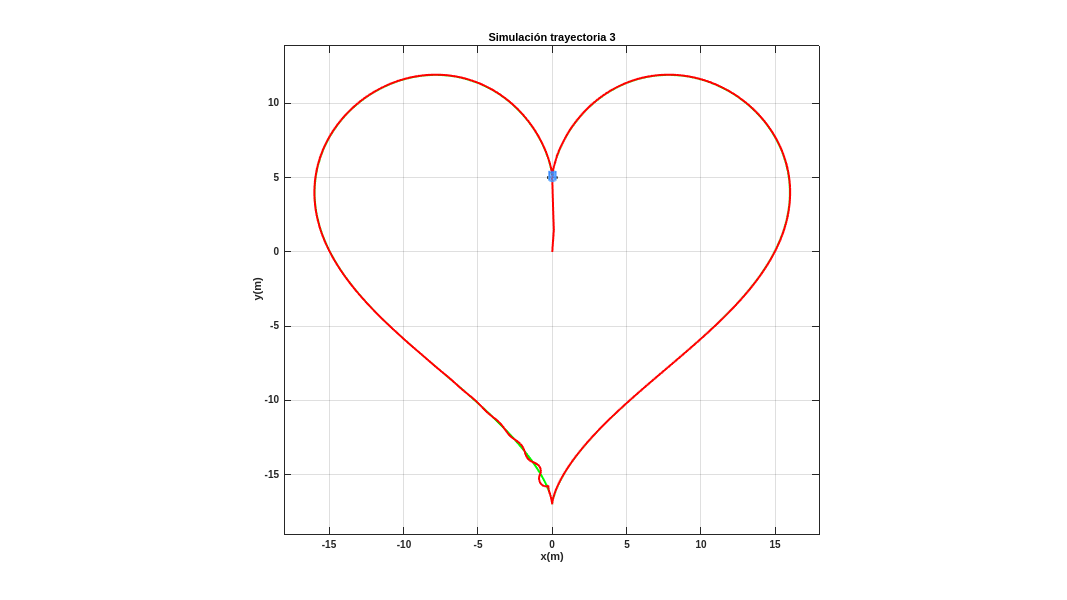

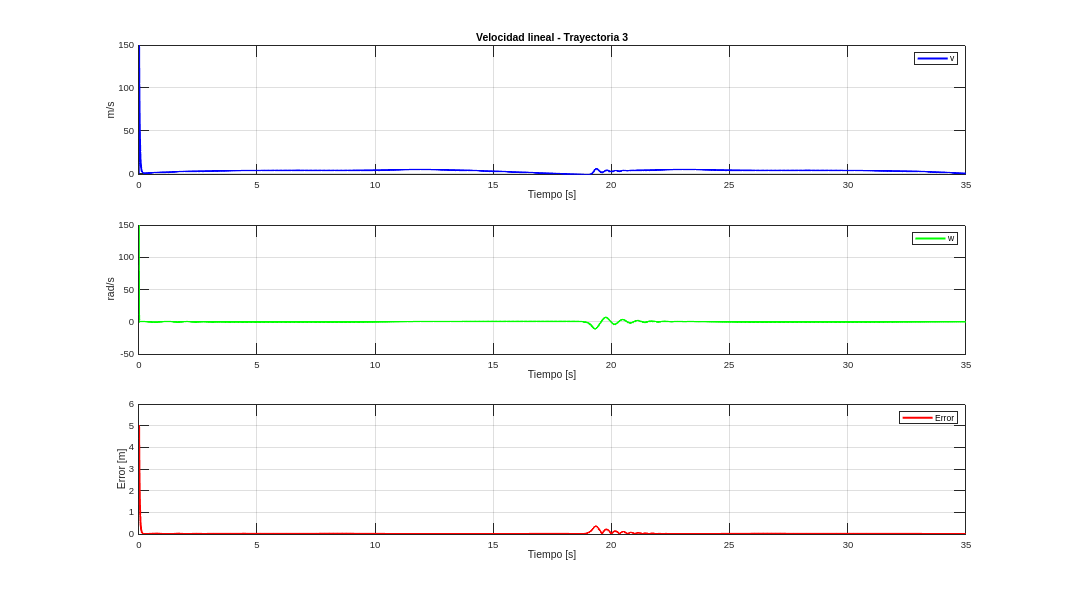

Simulación trayectoria 3 finalizada.




% 1. Tiempo de simulación
tf = 35;             % Tiempo de simulación en segundos
ts = 0.01;           % Tiempo de muestreo en segundos
t = 0:ts:tf;         % Vector de tiempo
N = length(t);       % Número de muestras

% 2. Definición de nuevas trayectorias (1-3)
theta = linspace(0,2*pi,N); % Parámetro general para trayectorias paramétricas

% Hexágono (trayectoria 1)
n = 6; % número de lados
theta_hex = linspace(0,2*pi,n+1); % ángulos de vértices
x_hex = cos(theta_hex); % vértices en x
y_hex = sin(theta_hex); % vértices en y
% Interpolar linealmente para que tenga N muestras
hxd_hex = interp1(linspace(0,1,length(x_hex)), x_hex, linspace(0,1,N));
hyd_hex = interp1(linspace(0,1,length(y_hex)), y_hex, linspace(0,1,N));

% Flor (trayectoria 2)
k = 9; a = 50; % 9 pétalos y tamaño
r_flor = a*sin(k*theta);
hxd_flor = r_flor .* cos(theta);
hyd_flor = r_flor .* sin(theta);

% Corazón (trayectoria 3)
hxd_corazon = 16*sin(theta).^3;
hyd_corazon = 13*cos(theta) - 5*cos(2*theta) - 2*cos(3*theta) - cos(4*theta);

% Guardamos en la celda trayectorias
trayectorias = {
    hxd_hex, hyd_hex;  % 1
    hxd_flor, hyd_flor; % 2
    hxd_corazon, hyd_corazon; % 3
};

% 3. Definición de ganancias K por cada trayectoria
ganancias_K = {
    [50 0; 0 15];  % 1. Hexágono
    [8 0; 0 8];    % 2. Flor
    [30 0; 0 30];  % 3. Corazón
};

% 4. Bucle para simular cada trayectoria
for caso = 1:3

    % Condiciones iniciales
    x1(1) = 0;
    y1(1) = 0;
    phi(1) = 0;

    hx(1) = x1(1);
    hy(1) = y1(1);

    % Trayectoria deseada
    hxd = trayectorias{caso,1};
    hyd = trayectorias{caso,2};

    % Derivadas aproximadas (velocidades deseadas)
    hxdp = [diff(hxd)/ts, 0];
    hydp = [diff(hyd)/ts, 0];

    % Prealocaciones
    Error = zeros(1,N);
    v = zeros(1,N);
    w = zeros(1,N);

    % Selección de la ganancia correspondiente
    K = ganancias_K{caso};

    % 5. Control, bucle de simulación
    for k = 1:N 
        hxe(k) = hxd(k) - hx(k);
        hye(k) = hyd(k) - hy(k);

        he = [hxe(k); hye(k)];
        Error(k) = sqrt(hxe(k)^2 + hye(k)^2);

        J = [cos(phi(k)) -sin(phi(k));
             sin(phi(k))  cos(phi(k))];

        hdp = [hxdp(k); hydp(k)];

        qpRef = pinv(J)*(hdp + K*he);

        v(k) = qpRef(1);
        w(k) = qpRef(2);

        % Aplicación de control
        phi(k+1) = phi(k) + w(k)*ts;

        xp1 = v(k)*cos(phi(k));
        yp1 = v(k)*sin(phi(k));

        x1(k+1) = x1(k) + ts*xp1;
        y1(k+1) = y1(k) + ts*yp1;

        hx(k+1) = x1(k+1);
        hy(k+1) = y1(k+1);
    end

    % 6. Simulación Virtual 3D

    figure;
    set(gcf,'Color','white');
    set(gca,'FontWeight','bold');
    sizeScreen = get(0,'ScreenSize');
    set(gcf,'position',sizeScreen);
    camlight('headlight');
    axis equal;
    grid on;
    box on;
    xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
    view([-0.1 90]);

    % ==== Nueva sección: ajustar límites automáticamente ====
    margen = 2; % margen adicional para que no quede pegado al borde
    x_min = min([hxd, hx]) - margen;
    x_max = max([hxd, hx]) + margen;
    y_min = min([hyd, hy]) - margen;
    y_max = max([hyd, hy]) + margen;
    axis([x_min x_max y_min y_max 0 1]); 
    % =======================================================

    title(['Simulación trayectoria ', num2str(caso)]);

    % b) Graficar robot en la posición inicial
    scale = 4;
    MobileRobot_5; % Asegúrate que esta función esté disponible
    H1=MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;

    % c) Graficar trayectorias
    H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
    H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); 

    step = 5; % pasos para la animación
    for k=1:step:N
        delete(H1);    
        delete(H2);

        H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
        H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);

        pause(ts);
    end

    % 7. Gráficas de velocidades y error
    figure;
    set(gcf,'position',sizeScreen);
    subplot(311)
    plot(t,v,'b','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('m/s'),legend('v');
    title(['Velocidad lineal - Trayectoria ', num2str(caso)]);
    subplot(312)
    plot(t,w,'g','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('rad/s'),legend('w');
    subplot(313)
    plot(t,Error,'r','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('Error [m]'),legend('Error');

    % Pausa para pasar al siguiente inciso
    disp(['Simulación trayectoria ', num2str(caso), ' finalizada.']);
end